% Base paths and clearing
clear all
clc
addpath functions/SETUP/
addpath functions/SENSE/
addpath functions/ACT/

% Setup Pi
[robotPi, blinkLED]= SETUP_pi("192.168.16.68");

% Setup Servos
robotServos = I2C_Servo_pHAT(robotPi);

ACT_moveCam(robotServos,90,40)

% Setup Sensors
[adcDevice1, adcDevice2] = SETUP_adc(robotPi);

% Setup PiCam
robotCam = cameraboard(robotPi,'Resolution','640x480');
SETUP_piCam(robotCam);  


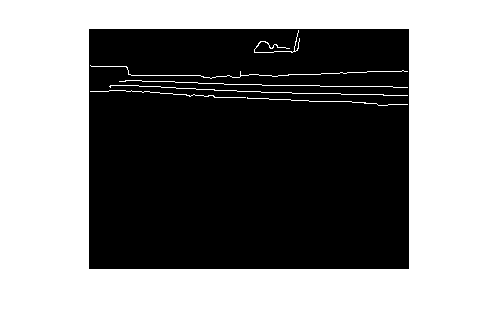

img = snapshotCustom(robotCam);


    img = rgb2gray(img);
    
    
    
    img = edge(img,"Canny",.5,"horizontal");
    
    img = bwareaopen(img, 100);


    [H,theta,rho] = hough(img);
    P = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
    lines = houghlines(img,theta,rho,P,'FillGap',5,'MinLength',7);
    
    img = snapshotCustom(robotCam);


    img = rgb2gray(img);
    
    
    
    img = edge(img,"Canny",.5,"horizontal");
    
    img = bwareaopen(img, 100);
    imshow(img)


    [H,theta,rho] = hough(img);
    P = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
    lines = houghlines(img,theta,rho,P,'FillGap',5,'MinLength',7);
    
    if isempty(lines)
        curve = generateBellCurve(30);
    else
        max_len = 0;
        
         for k = 1:length(lines)
            xy = [lines(k).point1; lines(k).point2];
            len = norm(lines(k).point1 - lines(k).point2);
           if ( len > max_len)
              max_len = len;
              xy_long = xy;
           end
        end


        if xy_long(2,1) > xy_long(1,1)
            change = xy_long(2,:) - xy_long(1,:);
        else
            change = xy_long(1,:) - xy_long(2,:);
        end

        angle = atand(-change(2)/change(1));

        disp(angle)
        
        center_angle = -5.7;

        if abs(angle - center_angle) < 2.5
            curve = createBellCurve(30);

        elseif angle < center_angle
            angle_offset = abs(angle - center_angle);
            curve = createBellCurve(30 + angle_offset);
        else
            angle_offset = abs(angle - center_angle);
            curve = createBellCurve(30 - angle_offset);
        end
        
    end

   -2.4366



while 1
    %ACT_moveRover(robotServos,0,0)
    curve = SENSE_piCam_line(robotCam);
    
    
    [~,steerangle] = max(curve);
    steerangle = steerangle - 30
    
    %pause(1)
    
    %ACT_moveRover(robotServos,steerangle,.4)
    
    pause(2)
end

     0



steerangle = -7

   12.2005



steerangle = -19

   12.9381



steerangle = -20

     0



steerangle = -7

     0



steerangle = -7

     0



steerangle = -7

     0



steerangle = -7

     0



steerangle = -7

     0



steerangle = -7

     0



steerangle = -7